# **AUTOMATED SIMULATION**

In this file we are going to analize two kind of controllers. In the first part we deal with anti-windup and feedforward, while in the second one we exploit the power of state-space techniques. This forst section clears the workspace and loads all the paramters that aree needed to perform simulations.

clear all
clc;

load('parameters.mat');
warning('off','all')

## 3.1 Preliminary configuration

#### Bias removing

bias.t0 = 0.2;
bias.t1 = 0.7;


## **3.2 Estimation of the elastic joint parameters**

## **3.3 Position PID control**

− perfect steady–state tracking of step position references (hub side)

− perfect steady–state rejection of constant torque disturbances (hub side)

− step response (hub side) with settling time ts,5% ≤ 0.85 s and overshoot Mp ≤ 30%.

% Required specs
perf.ts5 = 0.85;
perf.mp = 0.3;

perf.d = log(1/perf.mp)/sqrt(pi^2 + log(1/perf.mp)^2);
perf.wg = 3/(perf.d*perf.ts5);
perf.phi = 100*perf.d;

Since we observe that the pahse margin is below 70 degrees, we can apply the approximation above.

Now we have to determine the transfer function from

s = tf('s');
Dp = real.Jeq*beam.Jb*s^3 + (real.Jeq*beam.Bb+beam.Jb*real.Beq)*s^2 + (real.Beq*beam.Bb + joint.k*(real.Jeq + beam.Jb/(gbox.N^2)))*s + joint.k*(real.Beq + beam.Bb/(gbox.N^2));
P = drv.dcgain*mot.Kt*(beam.Jb*s^2 + beam.Bb*s + joint.k)/((gbox.N*s)*((sens.curr.Rs+mot.R)*Dp + mot.Ke*mot.Ke*(beam.Jb*s^2 + beam.Bb*s + joint.k)))

P =
 
           6.429e-06 s^2 + 1.561e-05 s + 0.003811
  ---------------------------------------------------------
  4.089e-08 s^4 + 1.373e-06 s^3 + 0.0002846 s^2 + 0.00138 s
 
Continuous-time transfer function.



We explot Bode Method to determine PID parameters

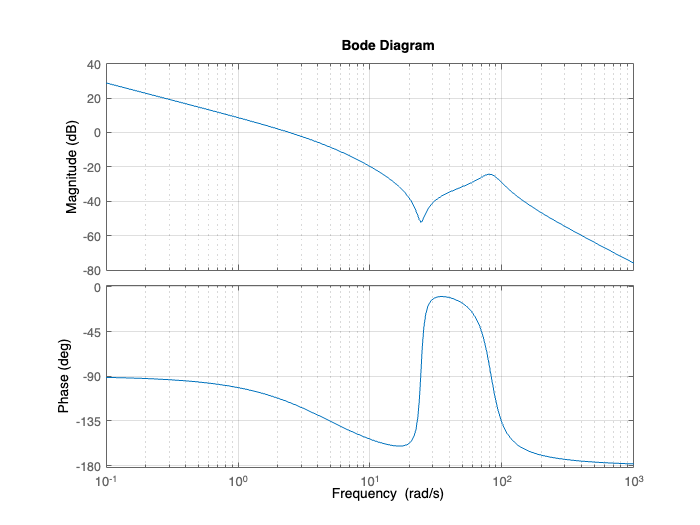

% Get magnitue and phase at the desired frequency
bode(P)
grid on

[magPwg, phasePwg] = bode(P, perf.wg)

magPwg = 0.1065

phasePwg = -152.9900

dK = abs(magPwg)^-1;
dPh = -pi + perf.phi*deg2rad - phasePwg*deg2rad;

pid.a = 4;                 
pid.K = dK * cos(dPh);
Td = (tan(dPh)+sqrt(tan(dPh)^2+4/pid.a))/(2*perf.wg);
Ti = pid.a*Td;

pid.Kd = pid.K*Td;
pid.Ki = pid.K/Ti;
disp(pid)

     a: 4
     K: 9.2768
    Kd: 0.5485
    Ki: 39.2267



Determine real derivative paramters for the PID and also for motor speed estimator

der.Tl = 1/(10*perf.wg);
der.wc = 2*pi*50;
der.d  = 1/sqrt(2);

Determine anti-windup parameters

awu.Tw = perf.ts5/5;
awu.Kw = 1/awu.Tw;

Simulations for the PID

simul.stepdeg = 50;
PID.deg_50 = sim('PID_Real','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
simul.stepdeg = 120;
PID.deg_120 = sim('PID_Real','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
save('PID.mat','PID');